%Specify result file route and name
fileNames = ["C:\Users\irene\Desktop\Universidad\Master\KTH\Segundo\Period 1\Research Methodology\Prefetcher-Simulation\results\605_no_output.json", "C:\Users\irene\Desktop\Universidad\Master\KTH\Segundo\Period 1\Research Methodology\Prefetcher-Simulation\results\605_spghb_output.json", "C:\Users\irene\Desktop\Universidad\Master\KTH\Segundo\Period 1\Research Methodology\Prefetcher-Simulation\results\605_spt_output.json"];
names_of_experiments = {'No prefetcher','GHB','SPT'};

% Initialize a cell array to store the JSON data
jsonData = cell(numel(fileNames), 1);
% Read the JSON files
for i = 1:numel(fileNames)
    fileName = fileNames{i};
    fileID = fopen(fileName, 'r');
    jsonData{i} = jsondecode(fread(fileID, inf, 'char=>char')');
    fclose(fileID);
end
%%Create directory to store graphs
mkdir('Results_Charts/605/');


fileNames = ["..\..\experiments\experiments_1C\605.mcf_s-472B_nopref.out","..\..\experiments\experiments_1C\605.mcf_s-472B_bingo.out","..\..\experiments\experiments_1C\605.mcf_s-472B_pythia.out", "..\..\experiments\experiments_1C\605.mcf_s-472B_sfp.out", "..\..\experiments\experiments_1C\605.mcf_s-472B_spt_v2.out"];
names_of_experiments = {'No prefetcher','Bingo', 'Pythia', 'SFP', 'SPT_V2'};
Data_from_simulations = cell(numel(names_of_experiments), 1);
for i = 1:numel(names_of_experiments)
    fileName = fileNames{i};
    Data_from_simulations{i} = parseResultFile(fileName);
end
% Display the structure containing the parameters
disp(Data_from_simulations);

    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}
    {1×1 struct}



mkdir('Results_Charts/');

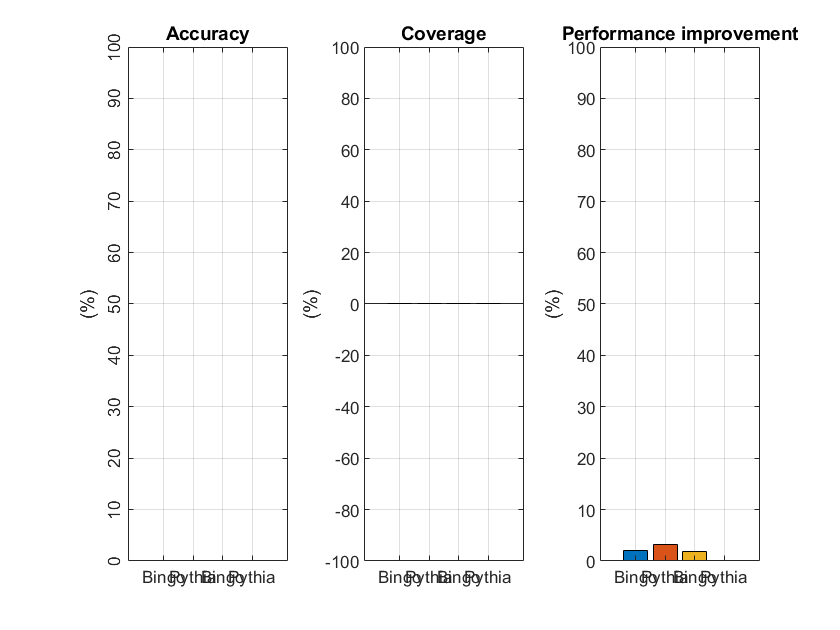


%Plot #1 : Accuracy
prefetched_blocks_read = zeros(numel(fileNames) - 1,1);
total_prefecthed = zeros(numel(fileNames) - 1,1);
accuracy = zeros(numel(fileNames) - 1,1);

for i = 2:numel(fileNames)
    prefetched_blocks_read(i - 1,1)=Data_from_simulations{i,1}.Core_0_L1D_prefetch_useful + Data_from_simulations{i,1}.Core_0_L1I_prefetch_useful;
    total_prefecthed(i - 1,1)=Data_from_simulations{i,1}.Core_0_L1D_prefetch_useless + Data_from_simulations{i,1}.Core_0_L1I_prefetch_useless;
    accuracy(i - 1,1)= 100 * (prefetched_blocks_read(i  - 1,1)/(total_prefecthed(i - 1,1)+prefetched_blocks_read(i - 1,1)));
end
subplot(1, 3, 1);
% Create a bar plot with custom colors
barHandle = bar(diag(accuracy), 'stacked');

% Customize the plot (optional)
ylim([0, 100]);
title('Accuracy');
ylabel('(%)');
ytickangle(90);
set(gca, 'XTickLabel', names_of_experiments(2:3)); % Set x-axis labels
grid on;

%saveas(gcf, 'Results_Charts/605/Accuracy_605.png');


%Plot #2 Coverage 
avoided_misses = zeros(numel(fileNames) - 1,1);
coverage = zeros(numel(fileNames) - 1,1);
for i = 2:(numel(fileNames))
    avoided_misses(i - 1,1)=(Data_from_simulations{1,1}.Core_0_L1D_load_miss - Data_from_simulations{i,1}.Core_0_L1D_load_miss);
    coverage(i - 1,1)= 100 * (avoided_misses(i - 1,1)/Data_from_simulations{1,1}.Core_0_L1D_load_miss );
end
subplot(1, 3, 2);
% Create a bar plot with custom colors
barHandle = bar(diag(coverage), 'stacked');

% Customize the plot (optional)
ylim([-100, 100]);
title('Coverage');
ylabel('(%)');
set(gca, 'XTickLabel', names_of_experiments(2:3)); % Set x-axis labels
grid on;

%saveas(gcf, 'Results_Charts/605/Coverage_605.png');

%Plot #3 Performance improvement
IPCprefetchers = zeros(numel(fileNames) - 1,1);
IPCbaseline = Data_from_simulations{1,1}.Core_0_IPC;
perf_improv = zeros(numel(fileNames) - 1,1);
for i = 2:numel(fileNames)
    IPCprefetchers(i-1,1)=(Data_from_simulations{i,1}.Core_0_IPC);
    perf_improv(i - 1,1)=100*(IPCprefetchers(i-1,1)/IPCbaseline - 1);
end
subplot(1, 3, 3);
% Create a bar plot with custom colors
barHandle = bar(diag(perf_improv), 'stacked');

% Customize the plot (optional)
ylim([0, 100]);
title('Performance improvement');
ylabel('(%)');
set(gca, 'XTickLabel', names_of_experiments(2:3)); % Set x-axis labels
grid on;
saveas(gcf, 'Results_Charts/Performance improvement_605.png');